# Implicit Deep Learning Tutorial on Synthetic Data

The impicit prediction rule reads


$$y=Ax+Bu+c\\
x=\phi(Dx+Eu+f)$$


we consider the well-posedness condition $\|D\|_\infty <1$. We consider the following dimensions $x\in R^h$, $u \in R^n$, $y \in R^p$ with matrices and vectors $A, B, c, D, E, f$ of corresponding appropriate dimensions. 

Let us start by drawing the real weights for the implicit model

n=10; h=100; p=5; density=0.3;
A=sprand(p,h,density).*(sign(rand(p,h)-0.5)); B=sprand(p,n,density).*(sign(rand(p,n)-0.5)); c=rand(p,1)-0.5;
D=sprand(h,h,density).*(sign(rand(h,h)-0.5)); E=sprand(h,n,density).*(sign(rand(h,n)-0.5)); f=rand(h,1)-0.5;
% project D to make it well-posed
funcs=UtilitiesIDL;
D=funcs.infty_norm_projection(D,0.1);

We denote $m$ the number of datapoints, we create our synthetic datatset. We consider that $u \sim \mathcal{N}(0,\Sigma_{\text{train}})$, where $\Sigma_{\text{train}}$ is a covariance matrix

Mat=funcs.RandOrthMat(n); Sigma_train=Mat'*diag(n*rand(n,1))*Mat; clear Mat;
% num of datapoint
m=5*10^2;
U = mvnrnd(zeros(n,1),Sigma_train,m)'; clear Sigma_train;
% find corresponding X using Picard iterations
X=funcs.picard_iterations(U,D,E,f);
Y=A*X+B*U+c*ones(1,m);

## (1) Training Using the Implicit Model

The RMSE at iteration 20 is: 5.4111
The RMSE at iteration 40 is: 4.4153
The RMSE at iteration 60 is: 3.9374
The RMSE at iteration 80 is: 3.608
The RMSE at iteration 100 is: 3.3612
The RMSE at iteration 120 is: 3.1684
The RMSE at iteration 140 is: 3.0137
The RMSE at iteration 160 is: 2.8871
The RMSE at iteration 180 is: 2.7817
The RMSE at iteration 200 is: 2.6927
The RMSE at iteration 220 is: 2.6165
The RMSE at iteration 240 is: 2.5506
The RMSE at iteration 260 is: 2.4929
The RMSE at iteration 280 is: 2.4419
The RMSE at iteration 300 is: 2.3965
The RMSE at iteration 320 is: 2.3555
The RMSE at iteration 340 is: 2.3182
The RMSE at iteration 360 is: 2.2841
The RMSE at iteration 380 is: 2.2527
The RMSE at iteration 400 is: 2.2237
The RMSE at iteration 420 is: 2.1967
The RMSE at iteration 440 is: 2.1716
The RMSE at iteration 460 is: 2.1481
The RMSE at iteration 480 is: 2.1261
The RMSE at iteration 500 is: 2.1054
The RMSE at iteration 520 is: 2.0859
The RMSE at iteration 540 is: 2.0675
The RM

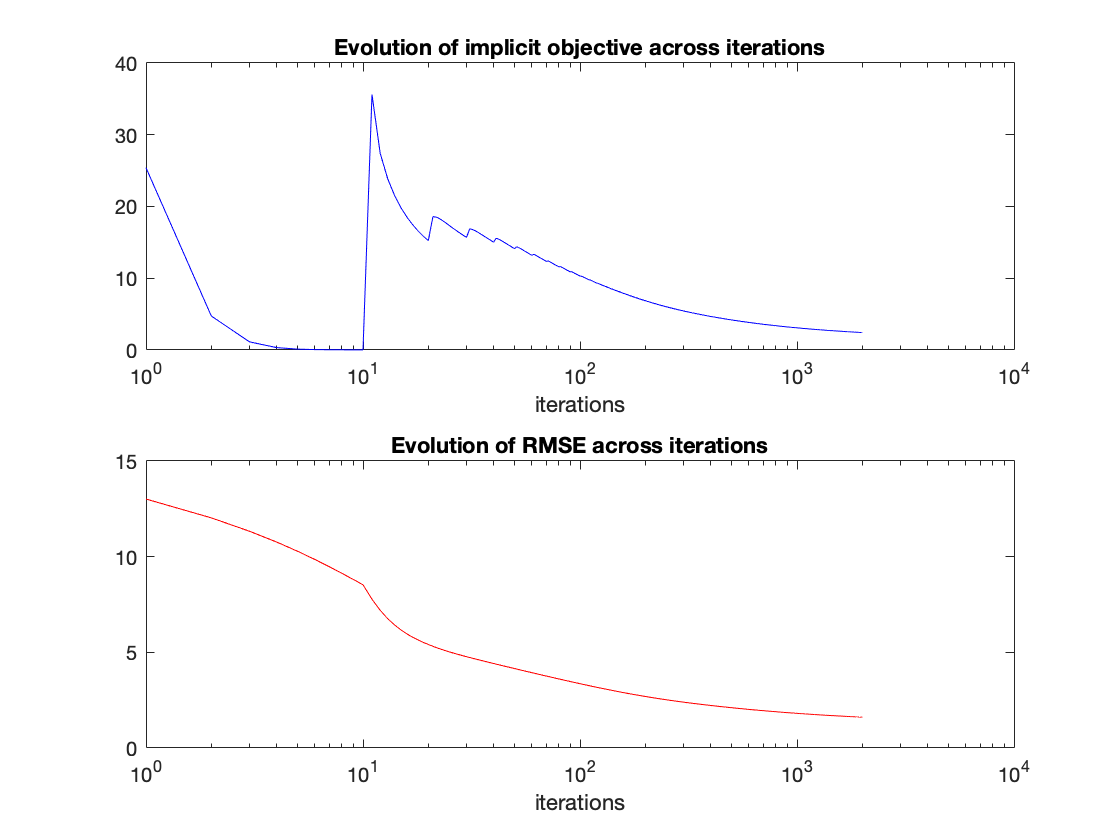

idl=ImplicitDeepLearning(U, Y, h, 2000, 10, 0.5); idl=idl.train; idl.visualize_algo;

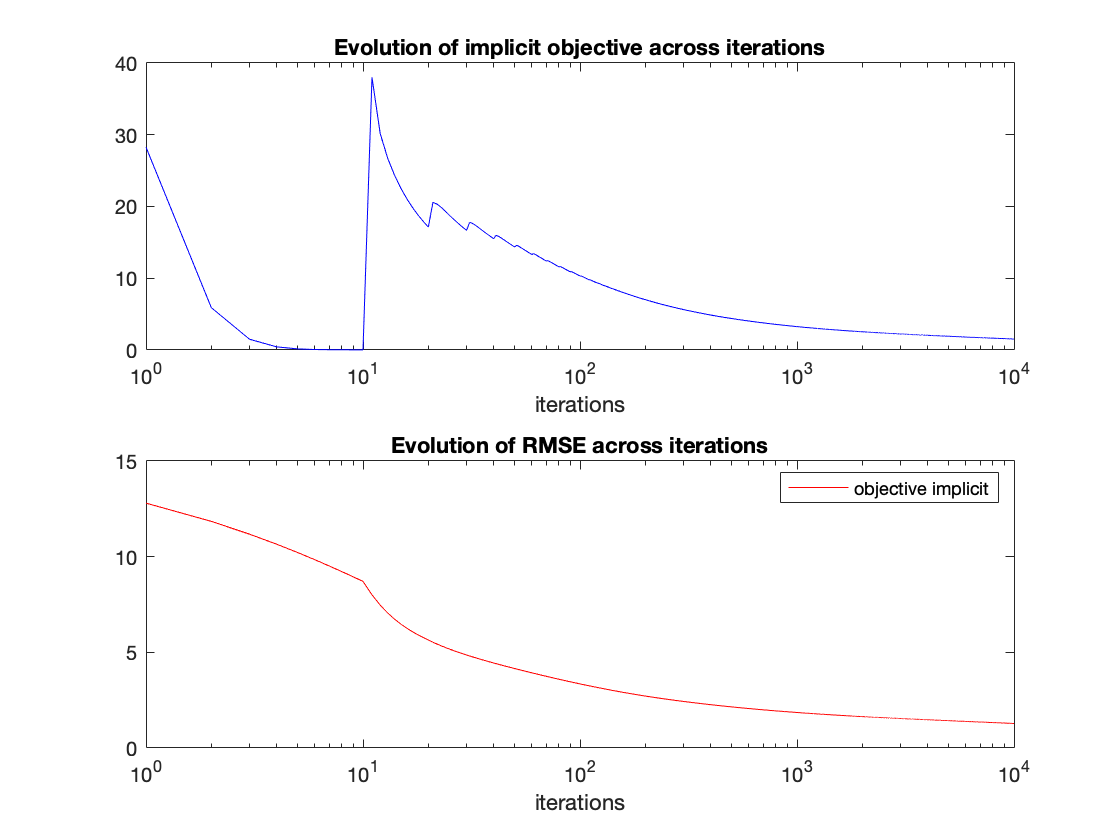

## (2) Linear model fit for comparison

We solve the following convex optimization problem instead (as a comparison)


$$\min_{B_{lin},c_{lin}}\|B_{lin}U+c_{lin}-Y\|_F$$


cvx_begin 
variable B_lin(p,n) 
variable c_lin(p,1)
minimize((1/sqrt(m))*norm(B_lin*U+c_lin*ones(1,m)-Y,'fro'))
cvx_end

 
Calling SDPT3 4.0: 2501 variables, 56 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 56
 dim. of socp   var  = 2501,   num. of socp blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.8e+01|1.4e+00|1.2e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.964|1.000|1.7e+00|4.3e-04|5.0e+02|-3.237372e+00 -1.209757e+01| 0:0:00| chol  1  1 
 2|1.000|1.000|9.7e-09|4.3e-05|1.0e+01|-1.546164e+00 -1.159741e+01| 0:0:00| chol  1  1 
 3|1.000|0.889|1.5e-09|8.6e-06|9.0e-01|-3.476636e+00 -4.376

Y_lin=B_lin*U+c_lin*ones(1,m);
disp(['The RMSE for the linear model is: ',num2str(funcs.RMSE(Y,Y_lin))]);

The RMSE for the linear model is: 4.1857


## (3) Neural Network Prediction rule for comparison

We fit a feedforward neural network model with 3 hidden layers of width $h$ (i.e. the total dimension of the hidden layer is $3h$ )

layers = [
    sequenceInputLayer(n)
    fullyConnectedLayer(h/2)
    reluLayer 
    fullyConnectedLayer(h/2)
    reluLayer
    fullyConnectedLayer(h/2)
    reluLayer
    fullyConnectedLayer(p)
    regressionLayer];

options = trainingOptions('rmsprop','MaxEpochs',10^3,'MiniBatchSize',m,'InitialLearnRate',10^-3);
net = trainNetwork(U,Y,layers,options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        10.29 |         52.9 |          0.0010 |
|      50 |          50 |       00:00:00 |         4.30 |          9.2 |          0.0010 |
|     100 |         100 |       00:00:01 |         2.50 |          3.1 |          0.0010 |
|     150 |         150 |       00:00:01 |         1.99 |          2.0 |          0.0010 |
|     200 |         200 |       00:00:02 |         1.83 |          1.7 |          0.0010 |
|     250 |         250 |       00:00:02 |         1.56 |          1.2 |          0.0010 |
|     300 |         300 |       00:00:03 |         1.46 |         

## Random functions

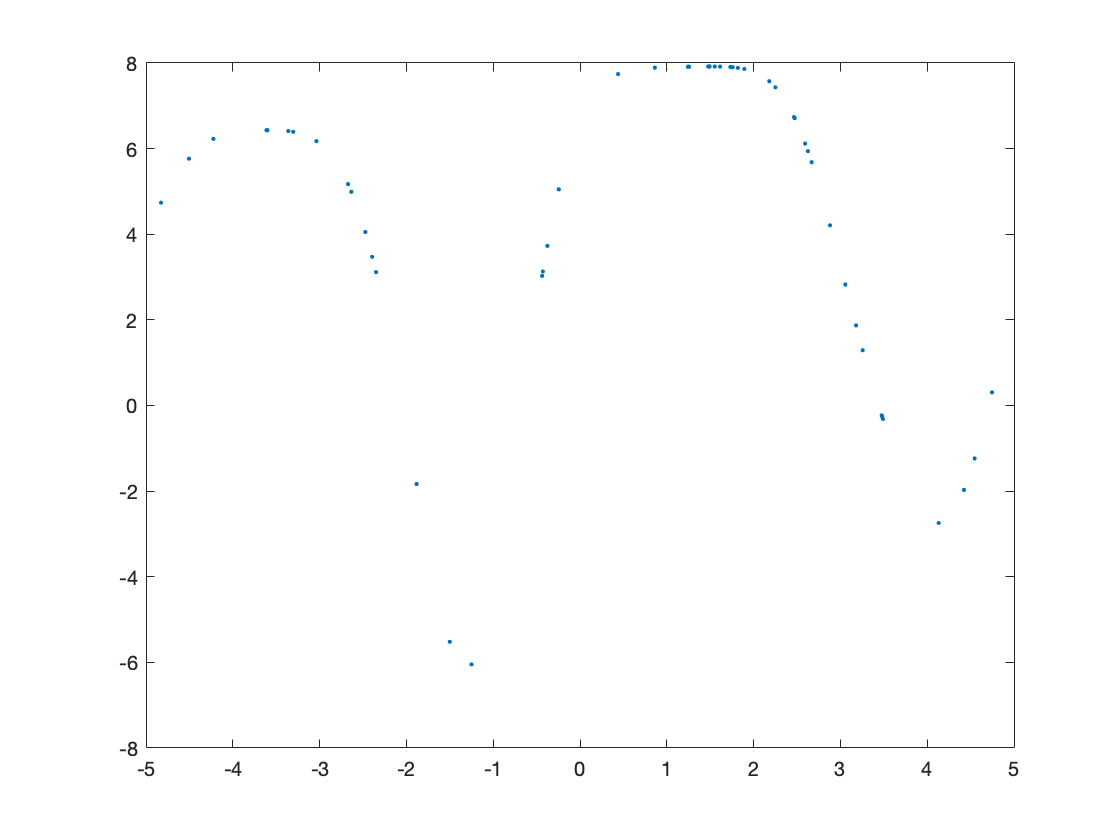

m =50;
num = 10;
alpha =2*(rand(num,1));
U_train = 10*(rand(1,m)-0.5);
Y_train = NaN* zeros(1,m);
for k =1:m
    Y_train(k) = 0;
    for i = 1:num
        Y_train(k) = Y_train(k)+alpha(i)*(sin(alpha(i)*U_train(k)+cos(alpha(i)*U_train(k)))); 
    end
end
figure()
plot(U_train, Y_train, '.');

The RMSE at iteration 50 is: 2.7037
The RMSE at iteration 100 is: 2.2471
The RMSE at iteration 150 is: 2.0391
The RMSE at iteration 200 is: 1.9213
The RMSE at iteration 250 is: 1.8501
The RMSE at iteration 300 is: 1.8058
The RMSE at iteration 350 is: 1.7765
The RMSE at iteration 400 is: 1.7557
The RMSE at iteration 450 is: 1.7386
The RMSE at iteration 500 is: 1.7233
The RMSE at iteration 550 is: 1.7094
The RMSE at iteration 600 is: 1.6965
The RMSE at iteration 650 is: 1.6844
The RMSE at iteration 700 is: 1.6721
The RMSE at iteration 750 is: 1.66
The RMSE at iteration 800 is: 1.648
The RMSE at iteration 850 is: 1.6363
The RMSE at iteration 900 is: 1.6248
The RMSE at iteration 950 is: 1.6135
The RMSE at iteration 1000 is: 1.6024
The RMSE at iteration 1050 is: 1.5913
The RMSE at iteration 1100 is: 1.5803
The RMSE at iteration 1150 is: 1.5694
The RMSE at iteration 1200 is: 1.5586
The RMSE at iteration 1250 is: 1.548
The RMSE at iteration 1300 is: 1.5374
The RMSE at iteration 1350 is: 1.526

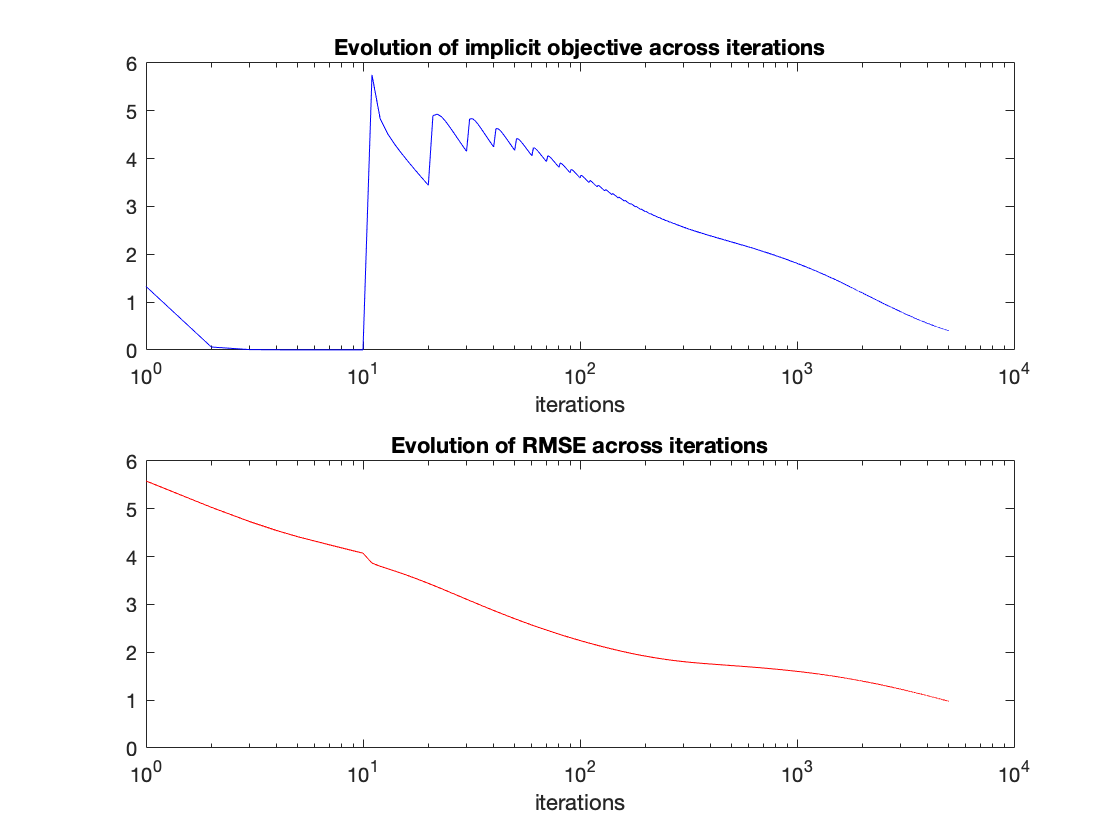

idl=ImplicitDeepLearning(U_train, Y_train, 200, 5000, 10, 0.5); idl=idl.train; idl.visualize_algo;

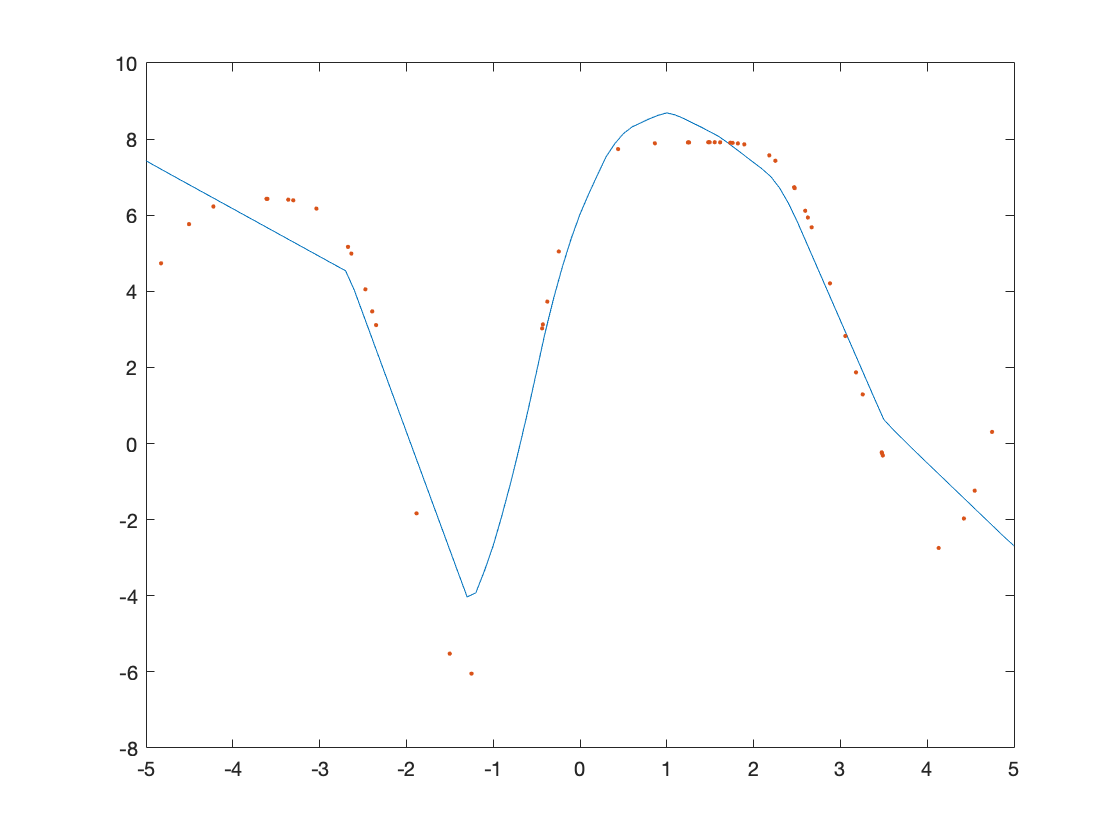

U = -5:0.1:5;
Y_prediction = idl.implicit_prediction(U);
figure()
plot(U, Y_prediction, '-')
hold on
plot(U_train, Y_train, '.');

layers = [
    sequenceInputLayer(1)
    fullyConnectedLayer(20)
    reluLayer 
    fullyConnectedLayer(20)
    reluLayer
    fullyConnectedLayer(20)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

options = trainingOptions('rmsprop','MaxEpochs',5*10^3,'MiniBatchSize',m,'InitialLearnRate',10^-3);
net = trainNetwork(U_train,Y_train,layers,options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         5.80 |         16.8 |          0.0010 |
|      50 |          50 |       00:00:00 |         4.98 |         12.4 |          0.0010 |
|     100 |         100 |       00:00:00 |         4.36 |          9.5 |          0.0010 |
|     150 |         150 |       00:00:01 |         4.11 |          8.5 |          0.0010 |
|     200 |         200 |       00:00:01 |         3.55 |          6.3 |          0.0010 |
|     250 |         250 |       00:00:02 |         2.72 |          3.7 |          0.0010 |
|     300 |         300 |       00:00:02 |         2.21 |         

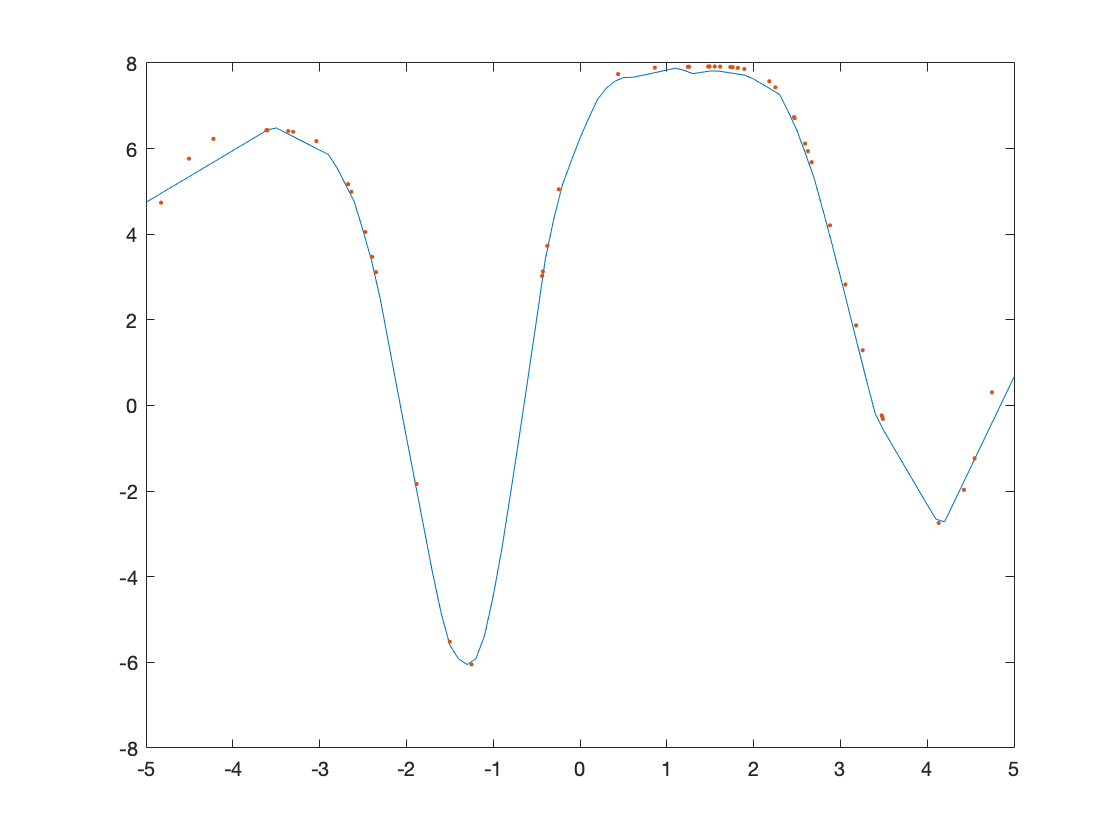

Y_prediction = predict(net,U);
figure()
plot(U, Y_prediction, '-')
hold on
plot(U_train, Y_train, '.');